# Spike Time Analysis 

Spiking actvitiy of neurons is the main focus of the [Steinmetz et al, 2019 paper](https://www.nature.com/articles/s41586-019-1787-x). In this livescript we will be visualising spikes from individual trials and cells

## Download and extract data

addpath(fullfile(fileparts(matlab.desktop.editor.getActiveFilename), "src"))
addpath(fullfile(fileparts(matlab.desktop.editor.getActiveFilename), "src/easyNC"))

download_from_sciebo("https://uni-bonn.sciebo.de/s/9QmOorFt6fTz4F0", "data/steinmetz_2017-01-08_Muller.nc")

Done!

addpath(fullfile(fileparts(matlab.desktop.editor.getActiveFilename), "data"))

ff = easyNC.Reader("data/steinmetz_2017-01-08_Muller.nc");

spike_data = ff.read2table(["spike_id","spike_trial","spike_time", "spike_cell"])

spike_data = 1836009×4 table
    spike_id    spike_time    spike_cell    spike_trial
    ________    __________    __________    ___________

        1         2.3629          1              1     
        2         2.3849          1              1     
        3         1.4507          1              2     
        4         1.4596          1              2     
        5         1.9635          1              2     
        6         1.9653          1              2     
        7         1.9708          1              2     
        8         1.9727          1              2     
        9         1.9751          1              2     
       10         1.9776          1              2     
       11         1.5432          1              6     
       12         1.5456          1              6     
       13         1.5476          1              6

## Visualize Spiking Activity with Scatter plots

The spiking activity is stored as a table. 

In this section we will select data from this table and visualise the spiking behaviour of single cells.

**Example Exercise**

Create a scatter plot to visualize spikes for a single neuron across multiple trials.

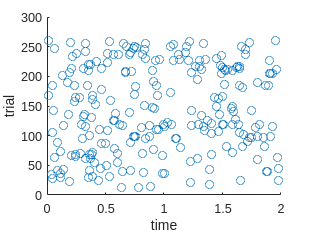

dd = spike_data(spike_data.spike_cell==12,:);
scatter(dd.spike_time, dd.spike_trial)
xlabel('time')
ylabel('trial')

**Exercises**

Create a scatter plot to visualize spikes for a neuron number 11 across multiple trials.

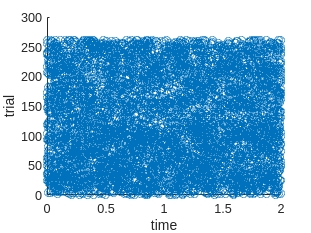

dd = spike_data(spike_data.spike_cell==11,:);
scatter(dd.spike_time, dd.spike_trial)
xlabel('time')
ylabel('trial')

Wow, that plot looks crowded! Instead of a circle,  remake the scatter plot with a horizontal bar : `|`

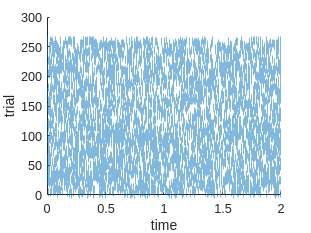

dd = spike_data(spike_data.spike_cell==11,:);
scatter(dd.spike_time, dd.spike_trial, "|")
xlabel('time')
ylabel('trial')

Create a scatter plot to visualize spikes for all neurons in trial 83.

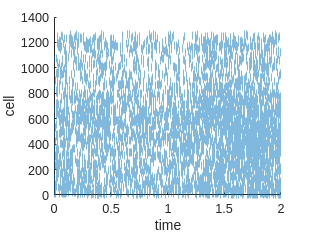

dd = spike_data(spike_data.spike_trial==83,:);
scatter(dd.spike_time, dd.spike_cell, "|")
xlabel('time')
ylabel('cell')

Remake the plot above, giving the plot an appropriate title

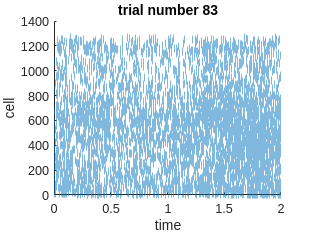

dd = spike_data(spike_data.spike_trial==83,:);
scatter(dd.spike_time, dd.spike_cell, "|")
xlabel('time')
ylabel('cell')
title('trial number 83')

## **Counting Spikes Across Trials **

The experiment is trial-based, such that we can extract meaningful results by analysing the data across all trials. 

In this section we will use table operations to learn about the number of neurons spiking across trials.

**Example Exercise**

How many spikes occurred during trial 1?

spike_cells_selected_trial = spike_data(spike_data.spike_trial==1,'spike_cell');
height(spike_cells_selected_trial)

ans = 9515

**Exercises**

How many spikes occurred during trial 24?

spike_cells_selected_trial = spike_data(spike_data.spike_trial==24,'spike_cell');
height(spike_cells_selected_trial)

ans = 7467

How many individual cells spiked during trial 24?

height(unique(spike_cells_selected_trial))

ans = 830

How many individual cells spiked during trial 108?

spike_cells_selected_trial = spike_data(spike_data.spike_trial==108,'spike_cell');
height(unique(spike_cells_selected_trial))

ans = 881

How many cells spiked during the last trial?

last_trial = spike_data.spike_trial(height(spike_data));
spike_cells_selected_trial = spike_data(spike_data.spike_trial==last_trial,'spike_cell');
height(unique(spike_cells_selected_trial))

ans = 919

Let's get the number of spiking cells per trial for all trials. To do this, we must group by the trial number and count the unique values of `spike_cell`

Perform this `groupsummary` below, naming the result `n_spiking_cells`

n_spiking_cells = groupsummary(spike_data, "spike_trial","numunique", "spike_cell")

n_spiking_cells = 261×3 table
    spike_trial    GroupCount    numunique_spike_cell
    ___________    __________    ____________________

         1            9515               860         
         2            8431               839         
         3            7868               809         
         4            8612               879         
         5            7739               836         
         6            7893               848         
         7            8323               824         
         8            7910               853         
         9            6362               796         
        10            7255               804         
        11            6621               813         
        12            6753               773         
        13            6601               824         
        14            8609               843         
   

What was the maximum number of spiking cells?

max(n_spiking_cells.numunique_spike_cell)

ans = 1001

What is the minimum number of spiking cells?

min(n_spiking_cells.numunique_spike_cell)

ans = 758

Let's visualize the distribution of the number of spiking cells with a histogram.

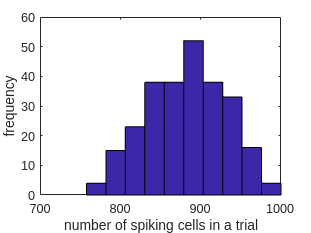

hist(n_spiking_cells.numunique_spike_cell)
xlabel('number of spiking cells in a trial')
ylabel('frequency')

## Relating spike timing to event-based variables

In this section, we will expand on the previous section and analyse spike time events jointly with other experimental events such as the `response_time.`

We will combine separate datasets into one table, while sorting and filtering the results.

**Load in data**

data_events = ff.read2table(["trial","response_time",  "gocue", "active_trials"])

data_events = 261×4 table
    trial     gocue     response_time    active_trials
    _____    _______    _____________    _____________

      1      0.98282        1.2333             1      
      2      0.90201        1.0666             1      
      3       1.1136        1.3666             1      
      4      0.68881        1.0168             1      
      5       1.0176        1.1834             1      
      6      0.61881       0.75082             1      
      7       1.0288        1.1841             1      
      8       1.0124        1.1505             1      
      9        1.112        2.6206             1      
     10      0.68121        1.2003             1      
     11      0.87641        2.3819             1      
     12      0.64841        2.1543             1      
     13        1.138        2.6443             1      
     14     

**Example Exercise**

Make a scatterplot of response time vs. trial number 

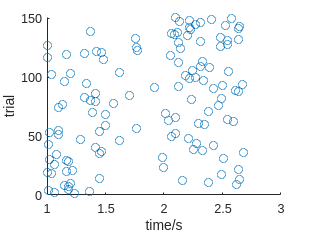

scatter(data_events.response_time, data_events.trial)
xlabel('time/s')
ylabel('trial')

Make a scatterplot of gocue time vs. trial number

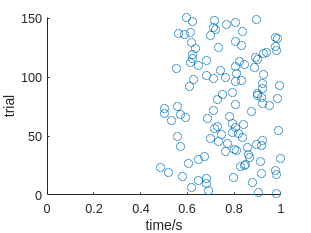

scatter(data_events.gocue, data_events.trial)
xlabel('time/s')
ylabel('trial')

Sort the rows of `data_events` by response time and name the result `data_events_sorted`

data_events_sorted = sortrows(data_events, "response_time");

Make a scatterplot of sorted response time vs.  the rank of the sorted response times

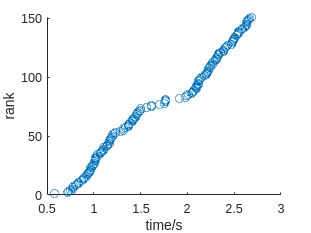

scatter(data_events_sorted.response_time, [1:height(data_events_sorted)])
xlabel('time/s')
ylabel('rank')

We want to add spiking events to the above plot. To do so however, we will need to sort the spiking events according to the response times. 

The first step is to combine the spiking and response data via a join. A join combines two tables by joining them along defined columns.

Fill in the blanks in the code below to perform the join

%spike_data = join(data, data_events, "LeftKeys","___", "RightKeys","___");
data = join(spike_data, data_events, "LeftKeys","spike_trial", "RightKeys","trial");


Find the rows of spike_data where the cell number is 48 and the trial is active ( ie. 1). Name the result `cell_48_active`

cell_48_active = data(data.spike_cell==48 & data.active_trials==1,:)

cell_48_active = 264×7 table
    spike_id    spike_time    spike_cell    spike_trial     gocue     response_time    active_trials
    ________    __________    __________    ___________    _______    _____________    _____________

     99236        1.1666          48             1         0.98282        1.2333             1      
     99237       0.24788          48             2         0.90201        1.0666             1      
     99238       0.34778          48             2         0.90201        1.0666             1      
     99239        0.2125          48             3          1.1136        1.3666             1      
     99240       0.34416          48             3          1.1136        1.3666             1      
     99241        0.6379 

Sort the rows of cell_48_active by the response time. Name the result `cell_48_active_sorted`

cell_48_active_sorted = sortrows(cell_48_active , "response_time");

The code below makes a scatter plot showing both the sorted response times and the sorted spike times vs. the response time rank. Fill in the blanks with the appropriate variables

This is known as a rasterplot

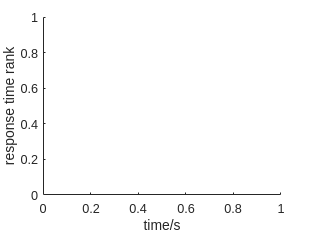

clf
hold on
%scatter(___.response_time, [1:height(___)],'.')
%scatter(___.spike_time, [1:height(___)],'.')
hold off
xlabel('time/s')
ylabel('response time rank')

Make a similar rasterplot but for cell 187

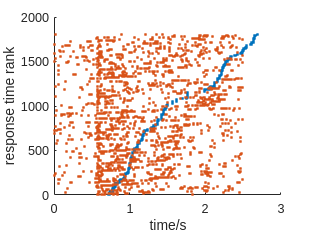

dd= data(data.spike_cell==187 & data.active_trials==1,:);
dd_sorted = sortrows(dd, "response_time");
clf
hold on
scatter(dd_sorted.response_time, [1:height(dd_sorted)],'.')
scatter(dd_sorted.spike_time, [1:height(dd_sorted)],'.')
hold off
xlabel('time/s')
ylabel('response time rank')

Why does neuron spiking activity increase dramatically after 0.5s for this cell? **Hint**- consider the distribution of timing events